clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");


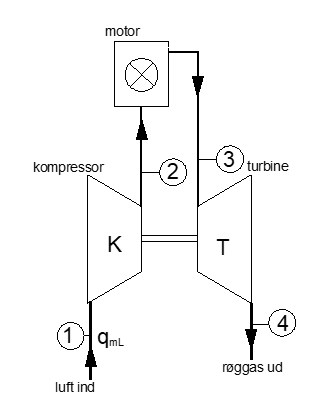

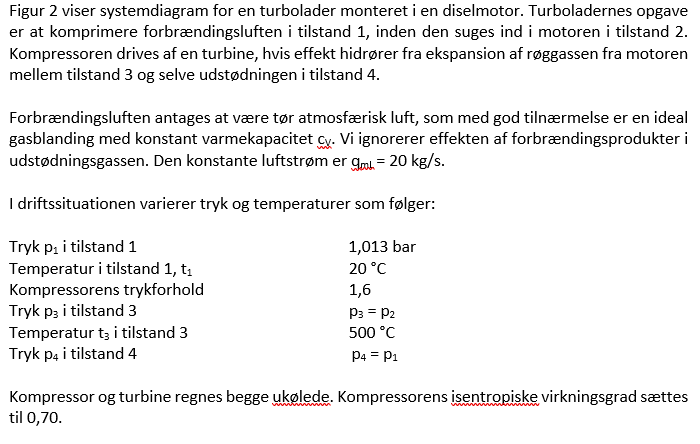

% Data fra opgaven
bar = 101325;
t0 = 273.15;

stof = "air"; % tør luft

t1 = 20; % celsius
t3 = 500;

p1 = 1*bar; % pascal
komp_tryk_forhold = 1.6;
p2 = p1 * komp_tryk_forhold

p2 = 162120

p3 = p2;
p4 = p1;

eta_isentrop = 0.7;


qml = 20; %kg/s

dens = CP.PropsSI("D", "T", t0+t1,"P",p1, stof)

dens = 1.2046

cv = CP.PropsSI("C", "T", t0+t1,"P",p1, stof)

cv = 1.0061e+03

Rl = 287;



$$\Phi_K + q_{ml}(h1-h2)=0\\
\Phi_T + q_{ml}(h3-h4)=0$$


For at finde aksel effekten, skal den isentropiske eksponent findes, ud fra $c_v$ og gaskonstanten. Det kan bruges til at finde den isentropiske T2s, der kan, med kendskab til den isentropiske virkningsgrad, bruges til at finde T2. Dernæst kan T1 og T2 ganges med den specifikke varmekapacitet, for at finde de specifikke entalpier, der benyttes til at beregne akseleffekten

is_eks = IsentropEksponent(cv, Rl)

Formlen for den isentrope eksponent bruges:


$$\kappa =\frac{c_{p}}{c_{p}-R_{i}}$$

Isentropeksponenten er fundet til 1.3991


is_eks = 1.3991


T2s = T2s_UdFraEksponent(nan, t1+t0, p1, p2, is_eks) % vigtigt at bruge Kelvin (fremgår af skemaet

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
          Variabel          Størrelse     Enhed
    ____________________    __________    _____

    "Isentropisk temp. "         335.2    "K"  
    ""                           293.2    "K"  
    "p1"                    1.0132e+05    "Pa" 
    "p2"                    1.6212e+05    "Pa" 
    "Isentrop eksponent"           1.4    "-"  



$$T2s = 335.2$$



h1 = (t1+t0)*cv;
h2s = (335.3)*cv;   
P_aksel = nan;

Pa = Kompressor_Koling_isentrop(qml,h1,h2s, P_aksel,eta_isentrop);

Energiligningen opstilles:


$$eq = -\frac{q_{\mathrm{mR}}\,\left(h_{1}-h_{\mathrm{2s}}\right)}{P_{a}}=\eta_{\mathrm{is}}$$

---------------------------------------------------
Hvor P_is er:


$$P_{\mathrm{is}}=q_{\mathrm{mR}}\,\left(h_{\mathrm{2s}}-h_{1}\right)$$

---------------------------------------------------
Der løses for: P_a


$$sol = -\frac{h_{1}\,q_{\mathrm{mR}}-h_{\mathrm{2s}}\,q_{\mathrm{mR}}}{\eta_{\mathrm{is}}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel            Størrelse      Enhed  
    ________________________    __________    ________

    "Phi isentrop"              8.4818e+05    "W"     
    "Massestrøm"                        20    "kg/s"  
    "h1"                        2.9495e+05    "J/kg*K"
    "h2s"                       3.3736e+05    "J/kg*K"
    "P_aksel"                   1.2117e+06    "W"     
    "Isentrop virkningsgrad"           0.7    "-"     



Med antagelse af at $\Phi_K = \Phi_T$ , skal den ukendte t4 bestemmes



t3 = t3 + t0;
h3 = t3*cv;
h4 = nan;
h4 = massestrom_all(-Pa, qml, h3, h4);

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: h_4


$$sol = \frac{\Phi +h_{1}\,q_{\mathrm{mR}}}{q_{\mathrm{mR}}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel       Størrelse     Enhed 
    ____________    ___________    ______

    "Phi "          -1211684.88    "W"   
    "Massestrøm"    20.0           "kg/s"
    "h3"            777900.26      "J/kg"
    "h4"            717316.01      "J/kg"




t4 = h4/cv

$$t4 = 712.93571428515880912280538654746$$



t4s = nan;
T4s = T2s_UdFraEksponent(t4s, t3, p3, p4, is_eks)

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse     Enhed
    _______________________    __________    _____

    "Isentropisk temp. t4s"         676.1    "K"  
    "t3"                            773.2    "K"  
    "p3"                       1.6212e+05    "Pa" 
    "p4"                       1.0132e+05    "Pa" 
    "Isentrop eksponent"              1.4    "-"  



$$T4s = 676.1$$


(t4 - t3)/(T4s - t3)

$$ans = 0.62072605289604305642997763883473$$

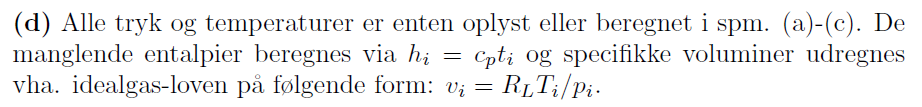

## Til funktioner